# Variant of the Stroop Task on Auditory, Semantic and Chronic Stimuli

By Kelly Brennan, Jamie Cho, and Alix McCabe

## Loading all of the available data

addpath('C:\Users\kelly_000\OneDrive\Documents\Olin 2017\NeuroTech\NeuroTech-Project-2\data');
data_folder = dir('data')

data_folder = 7×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


data_folder.name

ans = '.'

ans = '..'

ans = 'Data that doesn't work'

ans = 'stroop-subj1-run2.mat'

ans = 'stroop-subj2-run1.mat'

ans = 'stroop-subj3-run1.mat'

ans = 'stroop-subj4-run1.mat'

parse(data_folder(7).name)

ans = 120×1 cell array
    [ 687×4 single]
    [ 833×4 single]
    [ 514×4 single]
    [ 539×4 single]
    [ 438×4 single]
    [ 485×4 single]
    [ 308×4 single]
    [ 379×4 single]
    [ 481×4 single]
    [ 651×4 single]
    [ 529×4 single]
    [ 507×4 single]
    [ 537×4 single]
    [ 394×4 single]
    [ 497×4 single]
    [ 522×4 single]
    [ 404×4 single]
    [ 506×4 single]
    [ 502×4 single]
    [ 543×4 single]
    [ 432×4 single]
    [ 402×4 single]
    [ 365×4 single]
    [ 528×4 single]
    [ 504×4 single]
    [ 451×4 single]
    [ 589×4 single]
    [ 637×4 single]
    [ 724×4 single]
    [ 569×4 single]
    [ 456×4 single]
    [ 339×4 single]
    [ 758×4 single]
    [ 508×4 single]
    [ 450×4 single]
    [ 516×4 single]
    [ 498×4 single]
    [ 938×4 single]
    [ 625×4 single]
    [ 457×4 single]
    [ 381×4 single]
    [ 581×4 single]
    [ 484×4 single]
    [ 462×4 single]
    [ 388×4 single]
    [ 507×4 single]
    [ 450×4 single]
    [ 513×4 single]
    [ 381×4 singl

%[data_norm, stimulus_type, match_type, event_times] = [0,0,0,0]
[data_norm, stimulus_type, match_type, event_times] = parse(data_folder(4).name);
for i=5:7
    [data_norm_temp, stimulus_type_temp, match_type_temp, event_times_temp] = parse(data_folder(i).name);
    data_norm = vertcat(data_norm, data_norm_temp);
    stimulus_type = vertcat(stimulus_type,stimulus_type_temp);
    match_type = vertcat(match_type,match_type_temp);
    event_times = vertcat(event_times,event_times_temp);
    %[data_norm, stimulus_type, match_type, event_times; data_norm_temp, stimulus_type_temp, match_type_temp, event_times_temp]
end

%Setting up some global variables

match = data_norm{match_type == 1};
unmatch = data_norm{match_type == 0};
text_color = data_norm(stimulus_type == 1);
audio_text = data_norm(stimulus_type == 2);
color_audio = data_norm(stimulus_type == 3);

## Reaction Time

Reaction time defined as the time stamp from seeing the stimulus and the answe

RT_text_color = [];
RT_audio_text = []; 
RT_color_audio = []; 

ET_text_color = event_times(stimulus_type == 1);
ET_audio_text = event_times(stimulus_type == 2);
ET_color_audio = event_times(stimulus_type == 3);

for i = 1:size(ET_text_color)
   ET_temp = ET_text_color{i};
   RT_text_color(i,1) = ET_temp(end);
end
% RT_text_color

for i = 1:size(ET_audio_text)
   ET_temp = ET_audio_text{i};
   RT_audio_text(i,1) = ET_temp(end);
end
% RT_audio_text

for i = 1:size(ET_color_audio)
   ET_temp = ET_color_audio{i};
   RT_color_audio(i,1) = ET_temp(end);
end
% RT_color_audio

%RT_text_color = vertcat(RT_text_color,ET_text_color(1:end)(end))

We start by just plotting a histrogram of the reaction time and stimulus (AT, AC, CT) Or a box plot?

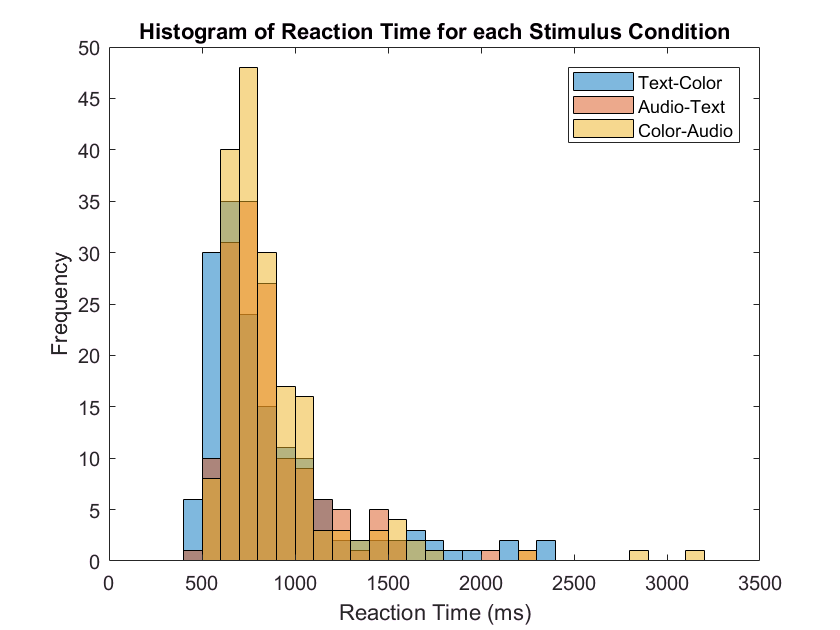

figure
binwidth = 100; %Since multiple histograms, we want to align the bin widths
facealpha = 0.5; %transparency of fill colors: 0 to 1
h1 = histogram(RT_text_color,'BinWidth',binwidth,'FaceAlpha',facealpha);
hold on; %make them on the same plot
h2 = histogram(RT_audio_text,'BinWidth',binwidth,'FaceAlpha',facealpha);
h3 = histogram(RT_color_audio,'BinWidth',binwidth,'FaceAlpha',facealpha);
ylabel('Frequency'); xlabel('Reaction Time (ms)'); title('Histogram of Reaction Time for each Stimulus Condition');
legend({'Text-Color','Audio-Text','Color-Audio'}); hold off;

Calculate the mean, median, mode, and std. of each stimulus condition

%Text-Color

RT_TC_mean = mean(RT_text_color)

RT_TC_mean = 853.4744

RT_TC_median = median(RT_text_color)

RT_TC_median = 726

RT_TC_mode = mode(RT_text_color)

RT_TC_mode = 560

RT_TC_std = std(RT_text_color)

RT_TC_std = 379.4516

RT_TC_var = var(RT_text_color)

RT_TC_var = 1.4398e+05

RT_TC_meanci = var(RT_text_color)

RT_TC_meanci = 1.4398e+05


RT_AC_mean = mean(RT_audio_text)

RT_AC_mean = 857.5417

RT_AC_median = median(RT_audio_text)

RT_AC_median = 786

RT_AC_mode = mode(RT_audio_text)

RT_AC_mode = 692

RT_AC_std = std(RT_audio_text)

RT_AC_std = 271.5180

RT_AC_var = var(RT_audio_text)

RT_AC_var = 7.3722e+04

RT_AC_meanci = var(RT_audio_text)

RT_AC_meanci = 7.3722e+04


RT_CA_mean = mean(RT_color_audio)

RT_CA_mean = 885.1444

RT_CA_median = median(RT_color_audio)

RT_CA_median = 788

RT_CA_mode = mode(RT_color_audio)

RT_CA_mode = 772

RT_CA_std = std(RT_color_audio)

RT_CA_std = 345.1847

RT_CA_var = var(RT_color_audio)

RT_CA_var = 1.1915e+05

RT_CA_meanci = var(RT_color_audio)

RT_CA_meanci = 1.1915e+05

% mean()
% median()
% mode()
% std()

ANOVA and effect size

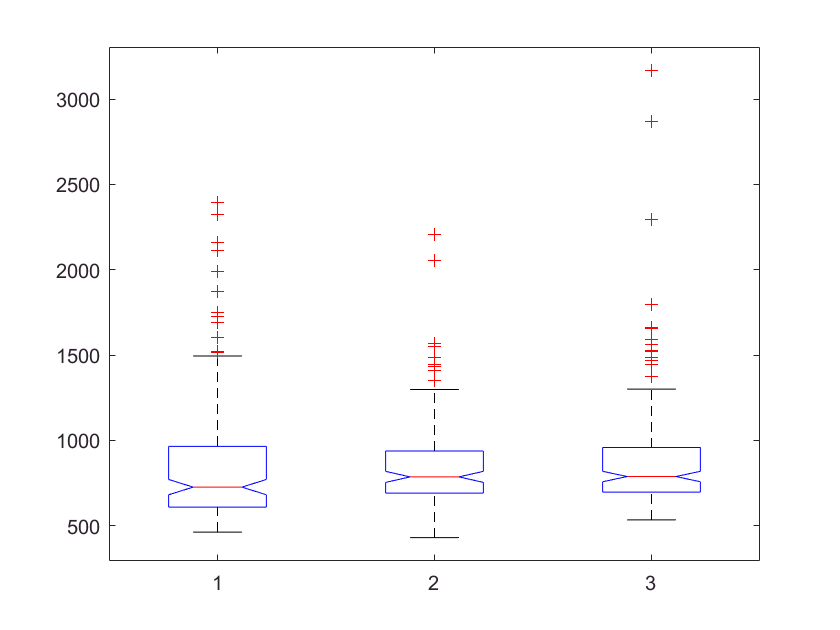

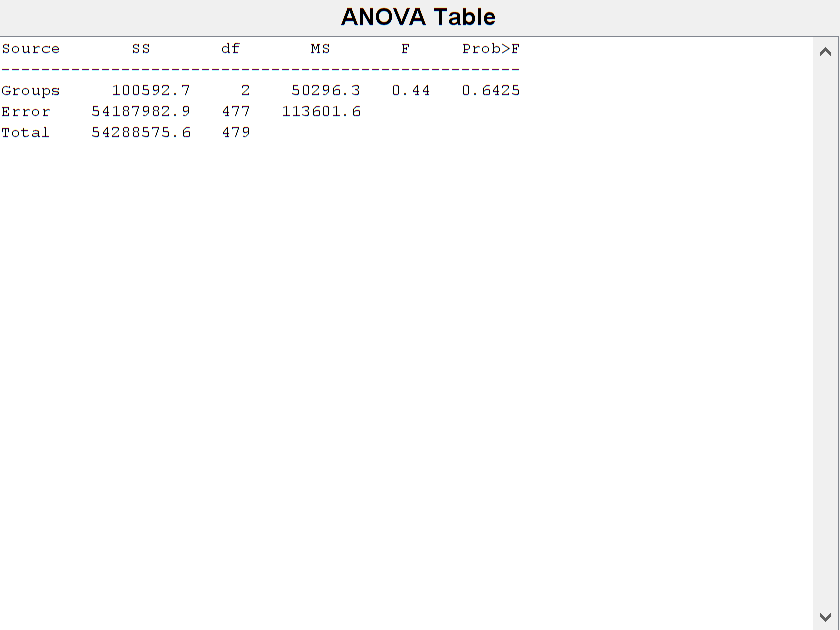

%Making a table
% T = table(RT_text_color, RT_audio_text, RT_color_audio);
max_RT_length = max([size(RT_text_color), size(RT_audio_text), size(RT_color_audio)]);

RT_text_color_expanded = [RT_text_color;NaN((max_RT_length(1) - length(RT_text_color)),1)];
RT_audio_text_expanded = [RT_audio_text;NaN((max_RT_length(1) - length(RT_audio_text)),1)];
RT_color_audio_expanded = [RT_color_audio;NaN((max_RT_length(1) - length(RT_color_audio)),1)];

[p, tbl, stats] = anova1([RT_text_color_expanded, RT_audio_text_expanded, RT_color_audio_expanded]);

etasquaredbetween = tbl{2,2}./tbl{4,2}

etasquaredbetween = 0.0019

Correlation of correctness and accuracy (maybe do some graphing? Can do more here)

sum(match_type(stimulus_type == 1))/length(match_type(stimulus_type == 1))

ans = 0.5128

sum(match_type(stimulus_type == 2))/length(match_type(stimulus_type == 2))

ans = 0.5278

sum(match_type(stimulus_type == 3))/length(match_type(stimulus_type == 3))

ans = 0.4667

% R1 = corrcoef(A,B)

%Repeat for the three conditions

## EEG Processing

Defined as the time stamp from seeing the stimulus and P300. (We may be also cuious about P600 too).

*Same as above. 

## Amplitude Intensity (and/our area under the curve)

Defined as the first definitive peak after exposure to the stimulus. Looking for a peak within a time range. 

Boxplot/historgram of the maximum amplitude with each stimulus condition

Calculate the mean, median, mode, and std. of each stimulus condition?

ANOVA & Effect size

How do the amplitudes correlate to reaction time?